# Control Fault Status D34 LED with PWM - Optional

Up to this point, we used the **D33 LED** to signal an **Over Load Fault** and the **D35 LED** to signal an **Over Current Fault**, but not highlighting an **OverLoad** with **No Fault**.

In this exercise, we will use **Pulse Width Modulation** signals to control a single LED** (D34 LED) **and highlight all Faults instead of using** 2 LEDs, **as follows:

- LED turned OFF - **No Fault**

- LED dimming with $\pi$ period  - **Over Load** with **No Fault**

- LED dimming with $4\pi$ period - **Fault Over Load (signal state more than 5s in the Over Load with No Fault)**

- LED continuously turned ON - **Fault** **Over Curent**

**S32K39** can generate PWM signals via the **eFlexPWM (Enhanced Flex Pulse Width Modulator)** or **eMIOS** **(Enhanced Modular IO Subsystem) **peripherals**.** For more details on the peripherals of the S32K39, also focusing on the Real-Time Control, please check the S32K39 Reference Manual.

### Set D34 as eFlexPWM output

According to the EVB schematics,** D34 LED** is connected to **PTD4** pin. This pin, can be muxed internally to the **PWM_0_A[3]**, meaning that we can use the **PWM module 0**, **Sub-Module 3, Channel A to generate a PWM **signal on this out pin.

As for the **Dio** pins,the **PTD4** pin needs to be routed to the **eFlexPWM** via the **S32CT** **Pins** **Tool,** together with the **Port** component. The settings are already performed in the S32CT project associated with the Simulink model.

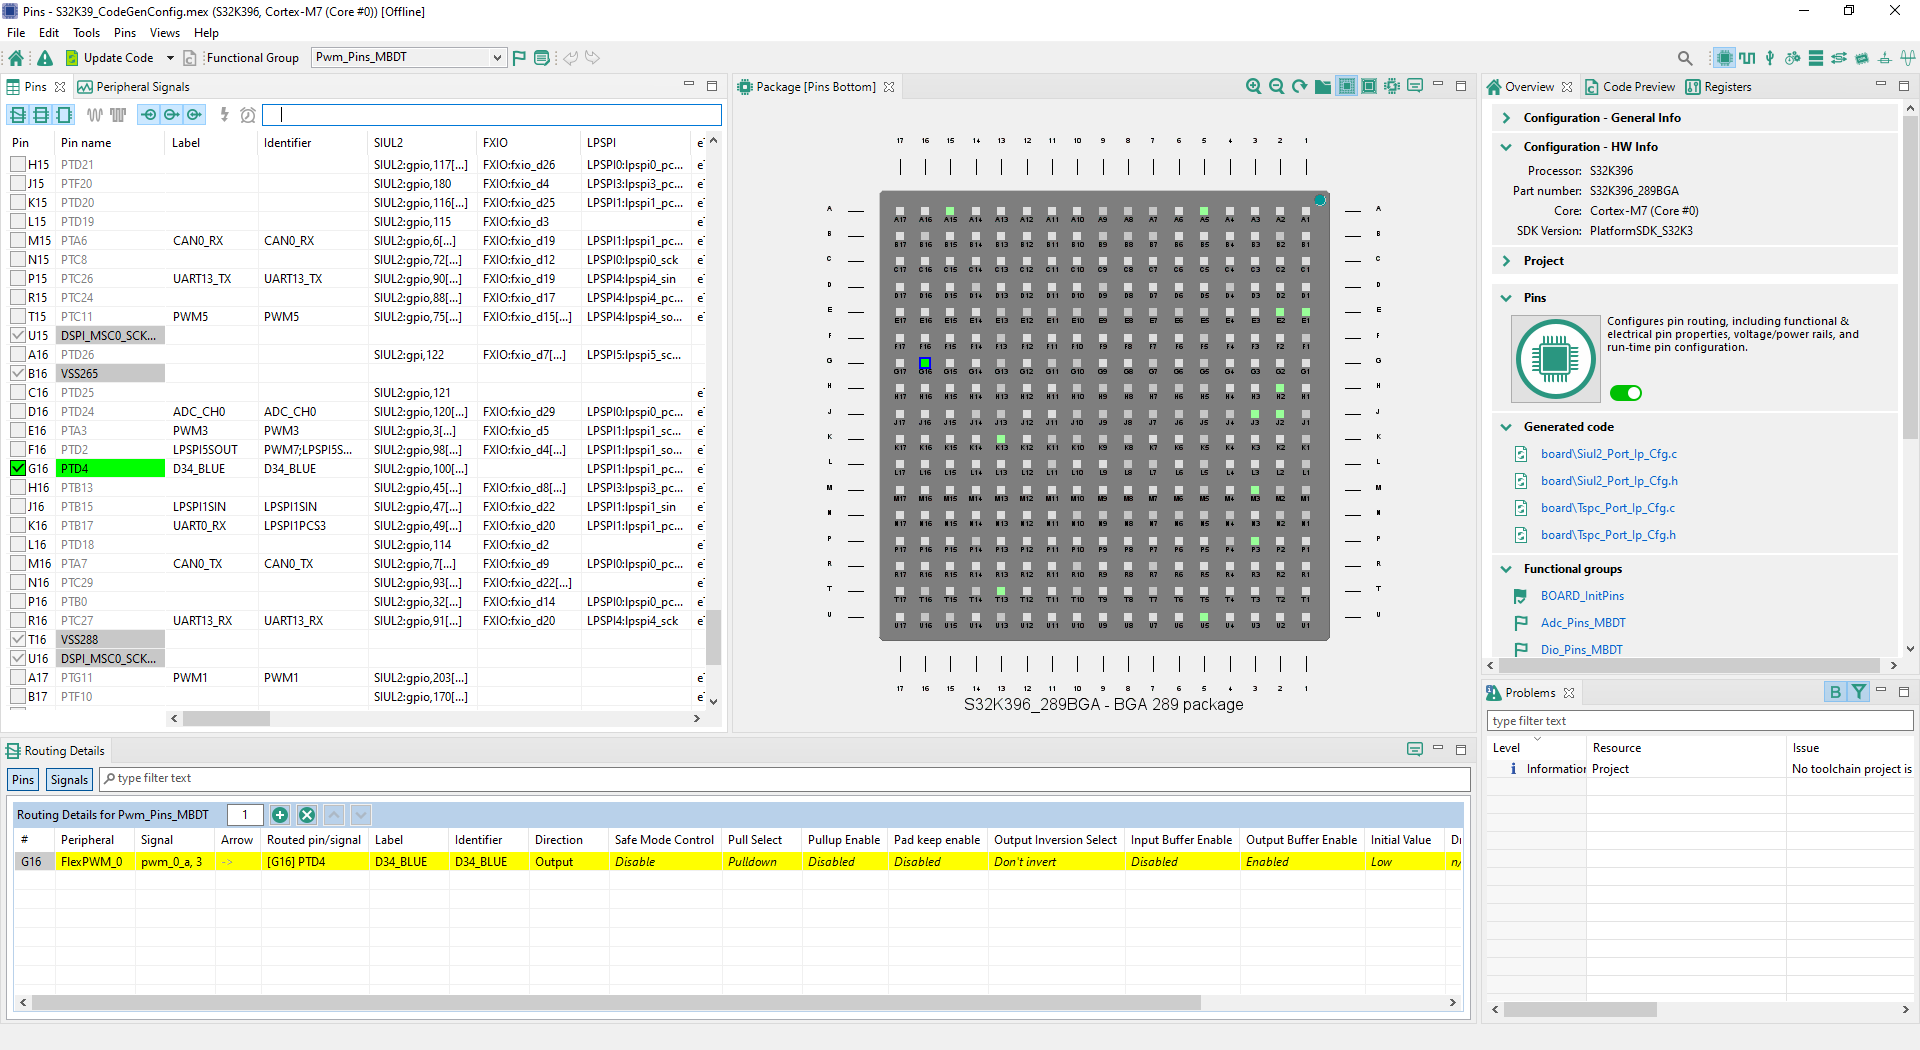

### eFlexPWM Configuration

To achieve the LED dimming effect, we need first to enable the PWM channel to deliver a carrier frequency for our sine of $\pi$ and $4\pi$ dimming period. Because we are aiming to control an LED intensity and the human eye cannot detect flickering above 50 or 90 Hz, we can configure the PWM carrier frequency to work at 100Hz.

First, the Pwm channel needs to be configured for the **S32CT**, **Pwm** component under **PwmChannelConfigSet -> FlexPwm Modules.** Here, the eFlexPWM SubModule_3, needs to be configured as in the screenshot below, also enabling the **FlexPWM Channel IP_PWMA**.

The typical formula for the Pwm frequency is: $F_{\mathrm{PWM}} =\frac{F_{\mathrm{OSC}} }{\mathrm{Prescaler}*\left(\mathrm{Period}+1\right)}$.

The frequency requested for the carrier signal is  $F_{\mathrm{PWM}} =100\mathrm{Hz}$, while according to the **Clocks Tool**, the $\mathrm{EFLEX}\_\mathrm{PWM0}\_\mathrm{CLK}=160\mathrm{MHz}$. Because the eFlexPWM counter is 16 bits wide, we need to select a Prescaler, so that the counter period for the 100Hz carrier frequency to be a value less than $2^{16} -1\ldotp$

Let's transform the formula so that we compute the Period: $\mathrm{Period}=\frac{F_{\mathrm{OSC}} }{\mathrm{Prescaler}*F_{\mathrm{PWM}} }-1$. With the Maximum prescaler of 128, the desired period becomes: $\mathrm{Period}=\;\frac{160\;\mathrm{MHz}}{128*100\mathrm{Hz}}-1=12499$.

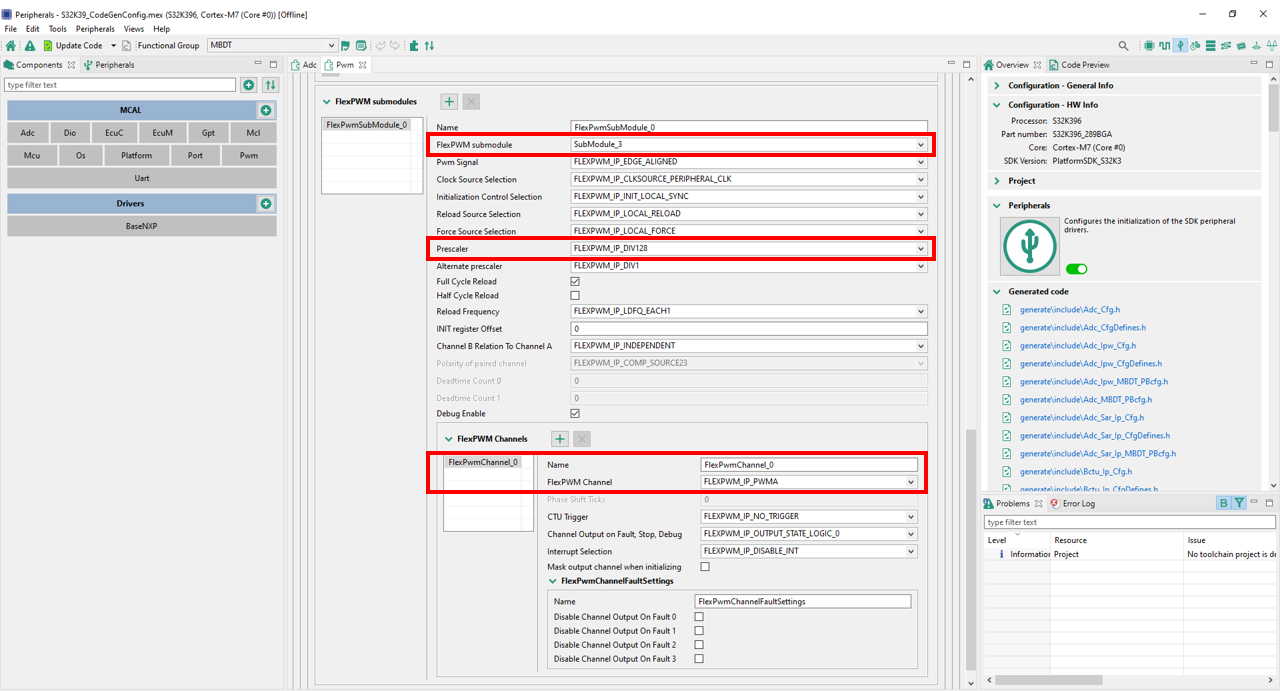

In the **Pwm driver -> PwmChannelConfigSet -> PwmChannel** we can add the **PwmChannel_D34** to point to the FlexPwmChannel_0 configured in the **FlexPwm Modules**, and type here the Default period to **12499.**

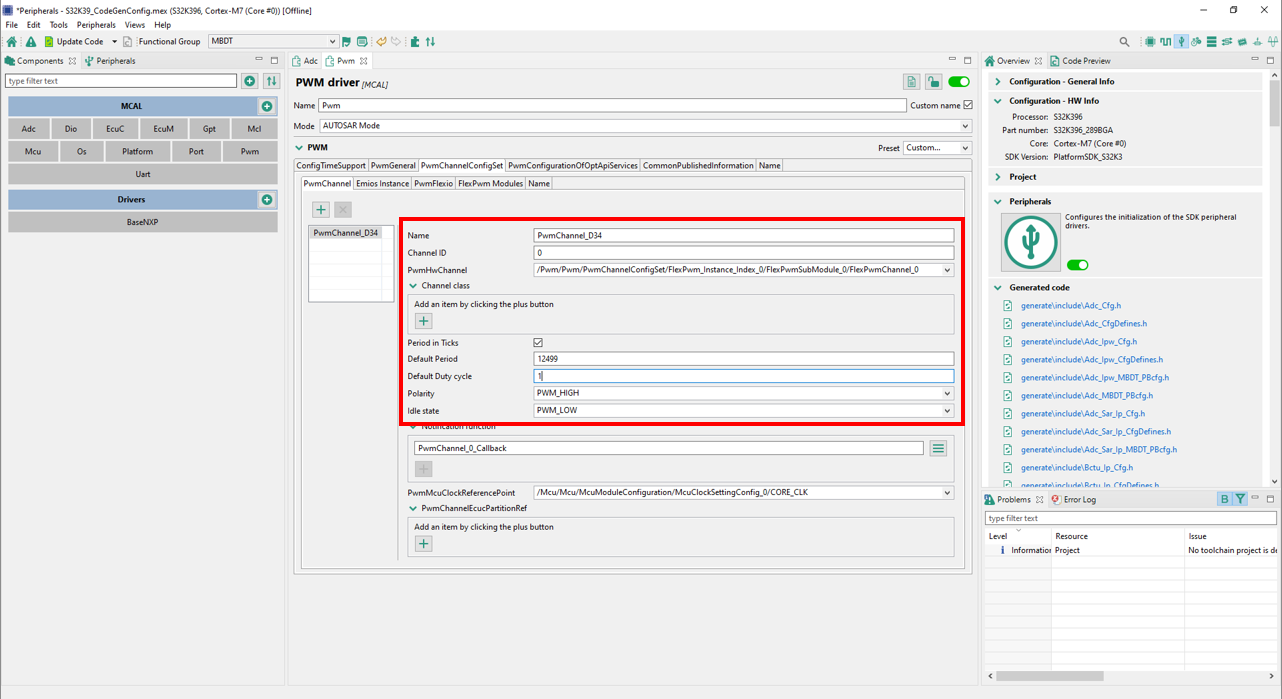

Please launch the **S32CT** and observe the Pins and Pwm settings.

### **Make an LED dimming with a desired frequency**

To make an LED dim with a desired frequency, we can use a Sine Wave generator block to provide the required duty cycle on top of our carrier frequency. With this block, we can set the Frequency in rad/sec as highlighted below.

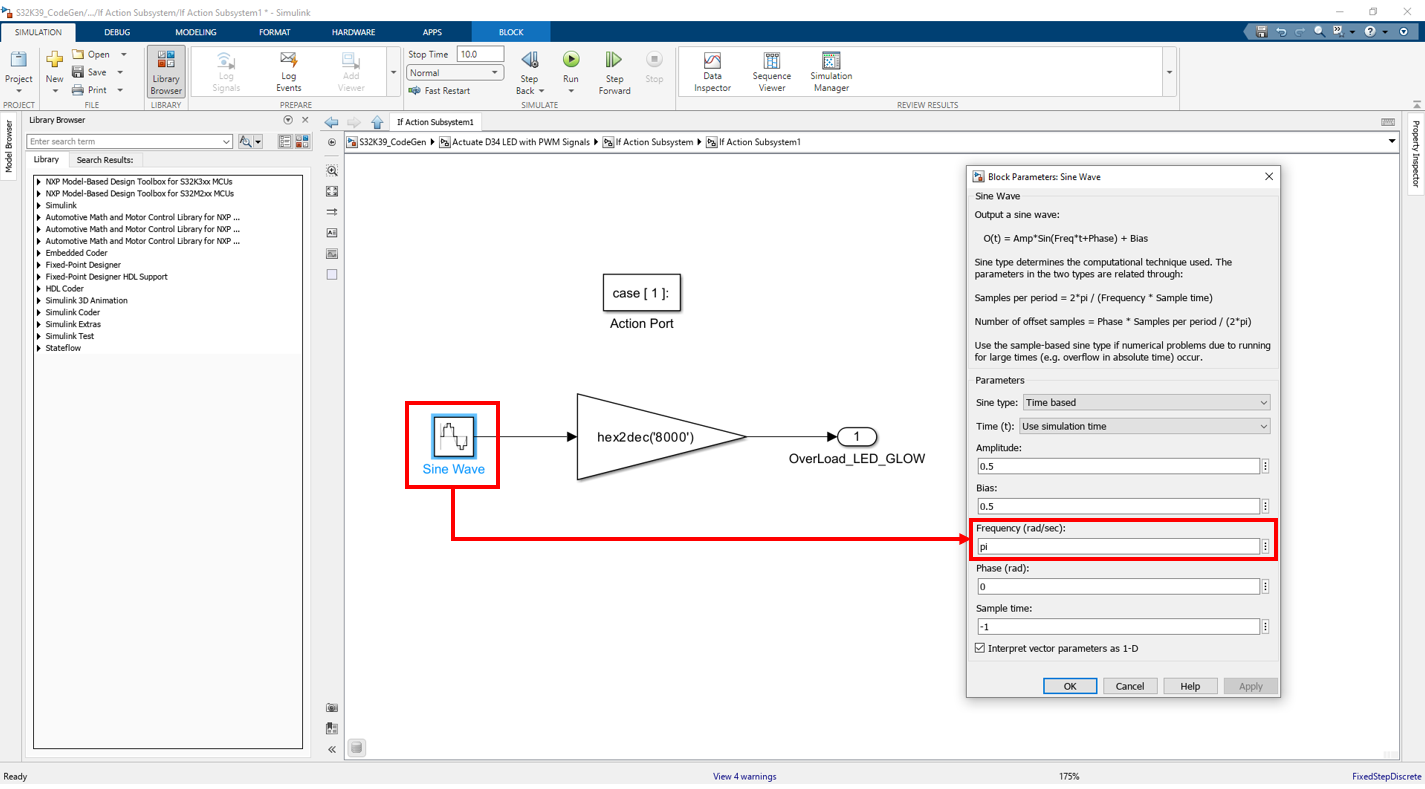

### PWM Control Duty Cycle

- Drag & drop a **Pwm** block in the model, from the Simulink Library Browser, under **S32K3xx Core, System, Peripherals and Utilities/IO Blocks** Library.

- Connect the **D34_PWM_ACTUATE **output from the subsystem **Actuate D34 LED with PWM Signals **to the input of **Pwm** block**.**

To change the intensity of the **D34_LED**, we need to update the duty cycle value for the PWM signal using the **Pwm** Block. The function which performs this action is** Pwm_SetDutyCycle**. Open the newly added block and make sure the **Pwm_SetDutyCycle** function is selected.

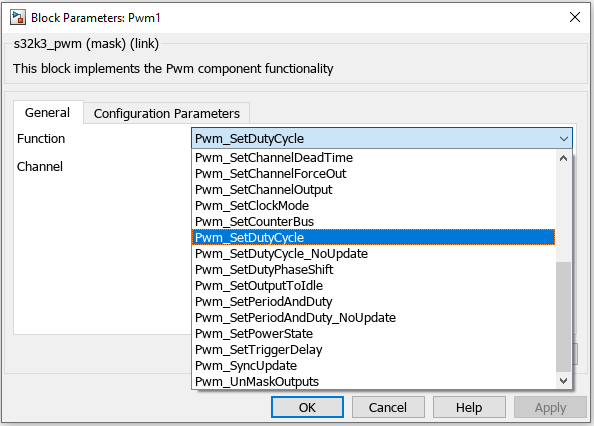

Once selected, the Pwm block is updated automatically to match the generated function signature. Select the **PwmChannel_D34** channel configured for **eFlexPWM_0_A[3]** routed to **D34_LED**. The duty cycle value is provided by the **Actuate D34 LED with PWM Signals** subsystem.

The function **Pwm_SetDutyCycle** sets the Pwm output state according to the configured polarity parameter, when the duty cycle = 0% or 100%. The function Pwm_SetDutyCycle modulates the Pwm output signal according to parameters period, duty cycle and configured polarity, when the duty cycle > 0 (0x0000) % and < 100% (0x8000).

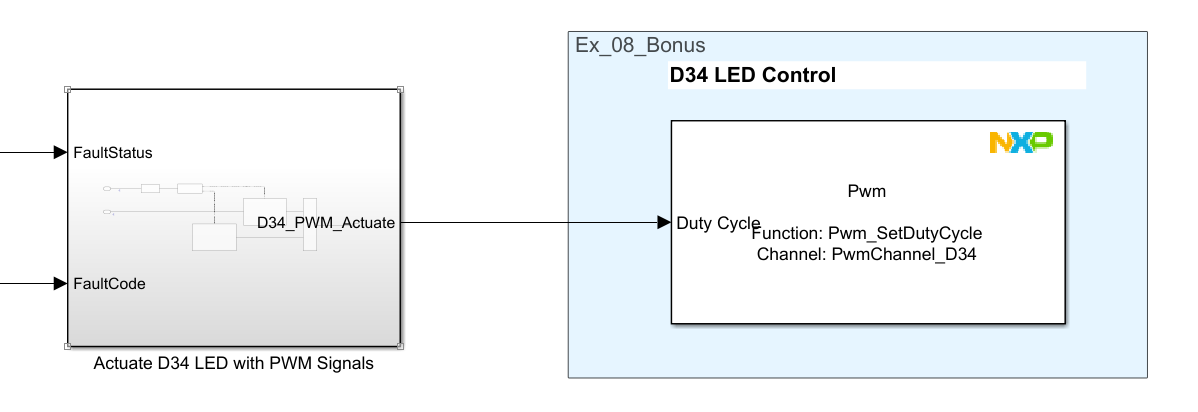

Generate, Build and Deploy the model to the board by pressing **Build, Deploy and Start **and observe the algorithm behavior**.**

For the Deploy exercises, the solution is available inside the following example:

open_system('S32K39_CodeGen_Solution');
